images = zeros(2400,2000);
for i = 1:10

 
    filename = strcat('data_',num2str(i));
    label_orig = eval(filename);
    %save the images
    images(:,((200*(i-1)+1):200*i))= label_orig(:,(1:200));
end

ball_07 = load("../Fault Dignosis/data/CWRU_data_LSTM/ball_07.mat");
ball_14 = load("../Fault Dignosis/data/CWRU_data_LSTM/ball_14.mat");
ball_21 = load("../Fault Dignosis/data/CWRU_data_LSTM/ball_21.mat");

inner_07 = load("../Fault Dignosis/data/CWRU_data_LSTM/inner_07.mat");
inner_14 = load("../Fault Dignosis/data/CWRU_data_LSTM/inner_14.mat");
inner_21 = load("../Fault Dignosis/data/CWRU_data_LSTM/inner_21.mat");

outer_07 = load("../Fault Dignosis/data/CWRU_data_LSTM/outer_07.mat");
outer_14 = load("../Fault Dignosis/data/CWRU_data_LSTM/outer_14.mat");
outer_21 = load("../Fault Dignosis/data/CWRU_data_LSTM/outer_21.mat");

normal_3 = load("../Fault Dignosis/data/CWRU_data_LSTM/normal_3.mat");

ball_07 = ball_07.X121_DE_time;
ball_14 = ball_14.X188_DE_time;
ball_21 = ball_21.X225_DE_time;

inner_07 = inner_07.X108_DE_time;
inner_14 =inner_14.X172_DE_time;
inner_21 = inner_21.X212_DE_time;

outer_07 = outer_07.X133_DE_time;
outer_14 = outer_14.X200_DE_time;
outer_21 =outer_21.X237_DE_time;

normal_3 = normal_3.X100_DE_time;


outer_m   = load("../Fault Dignosis/data/Bearing_data_mat/ver4/outer_m.mat");
inner_m   = load("../Fault Dignosis/data/Bearing_data_mat/ver4/inner_m.mat");
ball_m   = load("../Fault Dignosis/data/Bearing_data_mat/ver4/ball_m.mat");
normal_m = load("../Fault Dignosis/data/Bearing_data_mat/ver4/normal_m.mat");
outer_a   = load("../Fault Dignosis/data/Bearing_data_mat/ver4/outer_a.mat");
inner_a   = load("../Fault Dignosis/data/Bearing_data_mat/ver4/inner_a.mat");
ball_a   = load("../Fault Dignosis/data/Bearing_data_mat/ver4/ball_a.mat");
normal_a = load("../Fault Dignosis/data/Bearing_data_mat/ver4/normal_a.mat");

outer_m = outer_m.Acceleration;
inner_m = inner_m.Acceleration4;
ball_m = ball_m.Acceleration6;
normal_m = normal_m.Acceleration2;
outer_a = outer_a.Acceleration1;
inner_a = inner_a.Acceleration5;
ball_a = ball_a.Acceleration7;
normal_a = normal_a.Acceleration3;

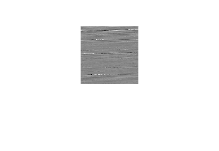

images = zeros(64,64);


images_size = 4096;
image_num = 125;

inner_scaling = floor((outer_m - min(outer_m)) / (max(outer_m) - min(outer_m))*255) ;




for i = 1:image_num
    if i == 1
        images = reshape(uint8(inner_scaling(1:images_size)),[64,64])';
    else
        images = reshape(uint8(inner_scaling(i*900 + 1 : (i*900)+ 4096)),[64,64])';
    end
    imshow(images);
    imwrite(images,strcat('O2_img_data_',num2str(i),'.jpg'),'JPG');

end